% 2024-12-04
% dataset is loaded by loadtxt
% 
clc
clear
% % 定义 MATLAB 中的矩阵 A 和 B
%  A = [1, 2, 3; 4, 5, 6];
%  B = [7, 8, 9; 10, 11, 12];
% % 
% % Transfer the A and B to Python script
% [result]=pyrunfile('matrix_sum.py', ["result"], A=A, B=B);
% 
% % Dispaly the result
% 
% disp('The result of matrix addition is:');
% disp(double(result));

% data generation 
disp('-----------------------------3d view------------------------------------')

-----------------------------3d view------------------------------------


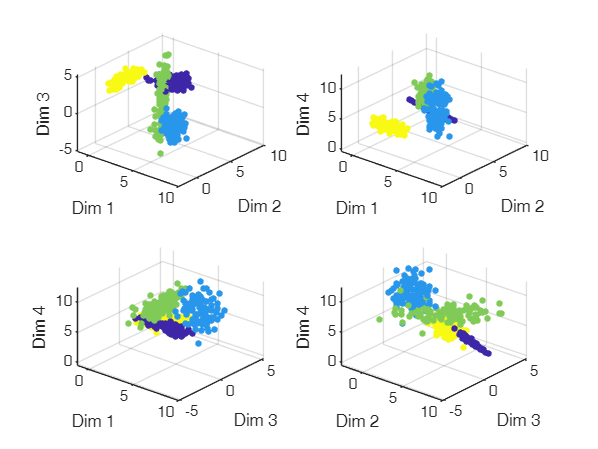

filename1=strcat('datasets/','SyntacticData4DimData.dat');
Synthetic_data=load(filename1,"-ascii");
filename2=strcat('datasets/','SyntacticData4DimLabel.dat');
Synthetic_rclass=load(filename2,"-ascii");
% 绘制数据（仅可视化维数为2或3时）
h1=figure(1);
subplot(2, 2, 1); 
scatter3(Synthetic_data(:,1), Synthetic_data(:,2), Synthetic_data(:,3), 15, Synthetic_rclass, 'filled');
xlabel('Dim 1');ylabel('Dim 2');zlabel('Dim 3');
view(40,35)
subplot(2, 2, 2); 
scatter3(Synthetic_data(:,1), Synthetic_data(:,2), Synthetic_data(:,4), 15, Synthetic_rclass, 'filled');
xlabel('Dim 1');ylabel('Dim 2');zlabel('Dim 4');
view(40,35)
subplot(2, 2, 3); 
scatter3(Synthetic_data(:,1), Synthetic_data(:,3), Synthetic_data(:,4), 15, Synthetic_rclass, 'filled');
xlabel('Dim 1');ylabel('Dim 3');zlabel('Dim 4');
view(40,35)
subplot(2, 2, 4); 
scatter3(Synthetic_data(:,2), Synthetic_data(:,3), Synthetic_data(:,4), 15, Synthetic_rclass, 'filled');
xlabel('Dim 2');ylabel('Dim 3');zlabel('Dim 4');
view(40,35)
% 显示结果
%disp('Data generated:');
%disp(Synthetic_data);
%disp('Labels:');
%disp(Synthetic_rclass);

saveas(h1,'SyntheticData4Dim2x2','pdf')

% 2-D view of the synthetic data

% 绘制数据（仅可视化维数为2或3时）
% disp('-----------------------------2d view------------------------------------')
% h2=figure(2);
% colors = [0.2, 0.6, 1; 
%           1, 0.5, 0.1; 
%           0.3, 0.8, 0.3; 
%           0.6, 0.2, 0.8];
% subplot(2, 3, 1); 
% for i=1:4
%     indx=find(Synthetic_rclass==i);
%     plot(Synthetic_data(indx,1), Synthetic_data(indx,2), '-o', 'Color',...
%              colors(i, :), 'MarkerFaceColor', colors(i, :));
%     hold on
% end
% xlabel('Dim 1');ylabel('Dim 2');
% view(40,35)
% subplot(2, 3, 2); 
% plot(Synthetic_data(:,1), Synthetic_data(:,3), 'filled');
% xlabel('Dim 1');ylabel('Dim 3');
% view(40,35)
% subplot(2, 3, 3); 
% plot(Synthetic_data(:,1), Synthetic_data(:,4), 'filled');
% xlabel('Dim 1');ylabel('Dim 4');
% view(40,35)
% subplot(2, 3, 4); 
% plot(Synthetic_data(:,2), Synthetic_data(:,3),'filled');
% xlabel('Dim 2');ylabel('Dim 3');
% view(40,35)
% subplot(2, 3, 5); 
% plot(Synthetic_data(:,2), Synthetic_data(:,4),'filled');
% xlabel('Dim 2');ylabel('Dim 4');
% view(40,35)
% subplot(2, 3, 6); 
% plot(Synthetic_data(:,3), Synthetic_data(:,4),'filled');
% xlabel('Dim 3');ylabel('Dim 4');
% view(40,35)

%saveas(h2,'SyntheticData4Dim2x3','pdf')

## FCM-matlab

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('FCM: matlab version')

FCM: matlab version


% use only 30 samples for simplificity
disp('FCM Algorithm-matlab')

FCM Algorithm-matlab


ndata = size(Synthetic_data, 1);          % number of data 
ndim = size(Synthetic_data, 2);           % number of dimension
Syntacticr_num=unique(Synthetic_rclass);
NumClusters=4;
options = fuzzy.clustering.FCMOptions(NumClusters=NumClusters, ...
                         Exponent=3.0,MinImprovement=1E-3, ...
                          Verbose=false);
for ii=1:options.NumClusters
    SyntacticB(ii,:)=find(Synthetic_rclass==Syntacticr_num(ii))';
end
Algs_info.name='fcm';

IterNum=1;
% All the distance between any two U{i} and U{j}
for ii=1:IterNum
    % centers: cluster centers (centers)   
    % U:  and a fuzzy partition matrix (U)
    % objFcn: the objective function values at each optimization 
    % iteration for the optimal number of clusters.
    % info:   the clustering results for all numbers of clusters used 
    % along with the validity index used for determining the optimal 
    % number of clusters. When the distance metric specified in options 
    % is either "mahalanobis" or "fmle", info also contains the covari
    % ance matrices generated for each number of clusters.
    [centers1(:,:,1),U1(:,:,1),objFcn(:,:,1),info(:,:,1)]...
          = fuzzy.clustering.fcm(Synthetic_data,options);
    maxU1 = max(U1(:,:,1)); 
    ind_tmp1=cell(1,options.NumClusters);
    for fcm_i=1:options.NumClusters
        index1 = find(U1(fcm_i,:,1) == maxU1);
        ind_tmp1{fcm_i}=index1;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index1,SyntacticB(kk,:)));
        end
        FcmNum(fcm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,1}=sum(FcmNum)/ndata   
end

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]}


disp('FCM----------------------------------------------------U1(:,:,1)')

FCM----------------------------------------------------U1(:,:,1)


U1(:,:,1)

ans =     0.1785    0.2268    0.1738    0.1452    0.1082    0.1411    0.1635    0.0248    0.1492    0.0936    0.1722    0.1775    0.0752    0.0855    0.0680    0.1627    0.1145    0.1433    0.1797    0.1673    0.0703    0.1554    0.1607    0.1649    0.2801    0.0945    0.1201    0.1377    0.2050    0.1669    0.1376    0.1248    0.1716    0.1366    0.1041    0.1024    0.2137    0.1361    0.1714    0.1856    0.1460    0.1425    0.2086    0.1864    0.1095    0.1446    0.0910    0.1640    0.1553    0.1163
    0.1856    0.1954    0.1962    0.1625    0.1089    0.1575    0.1506    0.0251    0.1656    0.0870    0.1978    0.1732    0.0726    0.0773    0.0689    0.1729    0.1177    0.1223    0.1904    0.1655    0.0697    0.1806    0.1807    0.1544    0.1925    0.0942    0.1124    0.1384    0.1623    0.1392    0.1495    0.1290    0.1902    0.1244    0.1121    0.1068    0.1709    0.1468    0.1872    0.1648    0.1335    0.1611    0.1912    0.1575    0.1180    0.1560    0.0946    0.1862    0.1319   

%disp(sprintf('The clusters for %d iterations',IterNum))

## 2: DIFCM: Python version

Iris 历时 x 秒。

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('DIFCM: Python version')

DIFCM: Python version


tic
% 1-norm,2-norm,inf-norm,fro-norm
DIFCM_norms=zeros(IterNum,4);
% Data+Label 
file_path1="datasets/SyntacticData4DimData.dat"

file_path1 = "datasets/SyntacticData4DimData.dat"

file_path2="datasets/SyntacticData4DimLabel.dat"

file_path2 = "datasets/SyntacticData4DimLabel.dat"

for ii=1:IterNum
    [norms,DIFCM_U]=pyrunfile("DI_FCMFuncDirPara.py",["norms","DIFCM_U"],...
                        file_path=file_path1);
    % ndarray-> matlab array
    pyList1 = norms.tolist(); % ndarray -> pylist
    %pylist-> cell array -> double array=
    result1 = cellfun(@double,cell(pyList1),'UniformOutput',false);
    DIFCM.norms(ii,:) = reshape(cell2mat(result1),[],4);
    %pylist-> cell array -> double array
    result2 = cellfun(@double,cell(DIFCM_U),'UniformOutput',false); 
    DICFM.U{ii}=reshape(cell2mat(result2),[],ndata);% cxn
    U3=DICFM.U{ii};
    maxU3 = max(U3); 
    ind_tmp3=cell(1,options.NumClusters);
    for difcm_i=1:options.NumClusters
        index3 = find(U3(difcm_i,:) == maxU3);
        ind_tmp3{difcm_i}=index3;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index3,SyntacticB(kk,:)));
        end
        DIFCMNum(difcm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,2}=sum(DIFCMNum)/ndata
end

File opened successfully.
[[0.91161526 6.5460307  1.4359949  3.4988971 ]
 [4.6006987  5.3362123  2.0907023  3.6738212 ]
 [1.2441087  7.7276871  1.8132888  2.3270563 ]
 ...
 [0.85794396 2.8242191  4.2147577  1.0336793 ]
 [0.83405423 2.3710669  3.5858033  2.2895139 ]
 [1.0053133  0.79648459 3.3440303  3.160405  ]]
400
4
5862.717180842688
5711.2395897607175
4311.0235230387225
2596.4879378455294
1659.754844523018
1576.5716883818561
1575.182507786108
1574.9284045479828
1574.8330748966307
1574.793092242788
1574.775997611607
1574.7686352984522
1574.7654510910295
1574.764070201171
1574.7634702991543
1574.7632093819764
1574.7630958143247
1574.7630463577855


FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]}


U1(:,:,2)=DICFM.U{1};
toc

历时 1.123198 秒。


disp('DIFCM----------------------------------------------U1(:,:,2)')

DIFCM----------------------------------------------U1(:,:,2)


U1(:,:,2)

ans =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9858    0.8932    0.9859    0.9977    0.9996    0.9980    0.9928    1.0000    0.9965    0.9997    0.9845    0.9857    1.0000    0.9999    0.9999    0.9929    0.9996    0.9971    0.9822    0.9928    0.9999    0.9944    0.9925    0.9929    0.6745    0.9999    0.9990    0.9985    0.9689    0.9925    0.9986    0.9995    0.9882    0.9974    0.9999    0.9999    0.9525    0.9990    0.9869    0.9823    0.9974    0.9977    0.9437    0.9817    0.9999    0.9978    1.0000    0.9915    0.9950   

## 3: OFCM: Python version

Iris 历时 x 秒。

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('------------------------------------------------------------')

------------------------------------------------------------


disp('oFCM: Python version')

oFCM: Python version


tic
file_path1="datasets/SyntacticData4DimDatL.csv"

file_path1 = "datasets/SyntacticData4DimDatL.csv"

% 1-norm,2-norm,inf-norm,fro-norm
oFCM_norms=zeros(IterNum,4);
for ii=1:IterNum
    [oFCM_U]=pyrunfile("oFCMFuncDirPara.py","oFCM_U",file_path=file_path1,...
                       Num_Cluter=NumClusters,data_siz1=ndata);
    % % ndarray-> matlab array
    % pyList1 = norms.tolist(); % ndarray -> pylist
    % %pylist-> cell array -> double array
    % result1 = cellfun(@double,cell(pyList1),'UniformOutput',false); 
    % oFCM.norms(i,:) = reshape(cell2mat(result1),[],4);
    %pylist-> cell array -> double array
    result3 = cellfun(@double,cell(oFCM_U),'UniformOutput',false); 
    oFCM.U{ii}=reshape(cell2mat(result3),[],ndata);% cxn
    U3=oFCM.U{ii};
    maxU3 = max(U3); 
    ind_tmp3=cell(1,options.NumClusters);
    for ofcm_i=1:options.NumClusters
        index3 = find(U3(ofcm_i,:) == maxU3);
        ind_tmp3{ofcm_i}=index3;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index3,SyntacticB(kk,:)));
        end
        oFCMNum(ofcm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,3}=sum(oFCMNum)/ndata
end

结束抽样的聚类
-----------------------------------------
第1份
结束抽样的聚类
----------------------------------------
第2份
结束抽样的聚类
----------------------------------------
第3份
结束抽样的聚类
----------------------------------------
结束抽样的聚类
准确度：87.5%
Time elapse：0.22812485694885254


FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]}


U1(:,:,3)=oFCM.U{1};
toc

历时 0.255222 秒。


disp('OFKM---------------------------------------------------U1(:,:,3)')

OFKM---------------------------------------------------U1(:,:,3)


U1(:,:,3)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1 

## 4: reskFCM: Python version

Iris 历时 x 秒。

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('------------------------------------------------------------')

------------------------------------------------------------


disp('reskFCM: Python version')

reskFCM: Python version


tic
% 1-norm,2-norm,inf-norm,fro-norm
reskFCM_norms=zeros(IterNum,4);
for ii=1:IterNum
    [reskFCM_U]=pyrunfile("reskFCMFuncDirPara.py","reskFCM_U",...
                 file=file_path1,Num_Cluter=NumClusters,data_siz1=ndata);
    % % ndarray-> matlab array
    % pyList1 = norms.tolist(); % ndarray -> pylist
    % %pylist-> cell array -> double array
    % result1 = cellfun(@double,cell(pyList1),'UniformOutput',false); 
    % oFCM.norms(i,:) = reshape(cell2mat(result1),[],4);
    %pylist-> cell array -> double array
    result4 = cellfun(@double,cell(reskFCM_U),'UniformOutput',false); 
    reskFCM.U{ii}=reshape(cell2mat(result4),[],ndata);% cxn
    U4=reskFCM.U{ii};
    maxU4 = max(U4); 
    ind_tmp4=cell(1,options.NumClusters);
    for reskfcm_i=1:options.NumClusters
        index4 = find(U4(reskfcm_i,:) == maxU4);
        ind_tmp4{reskfcm_i}=index4;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index4,SyntacticB(kk,:)));
        end
        reskFCMNum(reskfcm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,4}=sum(reskFCMNum)/ndata
end

准确度：80.0%
[[0.941642127292603, 0.023703837897062142, 0.02370053215571265, 0.010953502654622218], [0.058498383323589837, 0.10917892855728292, 0.10918045021337144, 0.7231422379057558], [0.9697915530280082, 0.012284025880849722, 0.012282129466379677, 0.005642291624762222], [0.038870072771600594, 0.43283555333649953, 0.4329805055035236, 0.09531386838837623], [0.007902719777949194, 0.4892510967089731, 0.48981035950399265, 0.01303582400908501], [0.6548930289479817, 0.13157101168771815, 0.13155898006736694, 0.08197697929693328], [0.019307131052417634, 0.056609720049813086, 0.056613224805696534, 0.8674699240920728], [0.20102612702803796, 0.34483976834863345, 0.3448475238804302, 0.10928658074289835], [0.004200508925924817, 0.010897722180710459, 0.01089794698101819, 0.9740038219123465], [0.07332436734946296, 0.3680159741711409, 0.36797613072979557, 0.19068352774960057], [0.12087523469046578, 0.42550345927316685, 0.12173683804428899, 0.3318844679920784], [0.14738039541328687, 0.25628276404486794,

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]}


U1(:,:,4)=reskFCM.U{1};
toc

历时 0.323319 秒。


% Results from 1: FCM-matlab, 2: DIFCM: Python version, 3: oFCM: Python
% version, 4: reskFCM: Python version, 
disp('ReskFCM------------------------------------------------U1(:,:,4)')

ReskFCM------------------------------------------------U1(:,:,4)


U1(:,:,4)

ans =     0.9416    0.0585    0.9698    0.0389    0.0079    0.6549    0.0193    0.2010    0.0042    0.0733    0.1209    0.1474    0.3138    0.0345    0.1263    0.2276    0.4171    0.1072    0.6770    0.4242    0.3572    0.2484    0.0233    0.1669    0.2401    0.1305    0.2584    0.3786    0.1621    0.1526    0.3579    0.4272    0.5037    0.3356    0.2063    0.3484    0.5022    0.1206    0.4443    0.1517    0.3409    0.1310    0.0365    0.0484    0.3721    0.0958    0.1377    0.1393    0.4969    0.2695
    0.0237    0.1092    0.0123    0.4328    0.4893    0.1316    0.0566    0.3448    0.0109    0.3680    0.4255    0.2563    0.2292    0.5692    0.2155    0.5339    0.3401    0.3790    0.1477    0.4191    0.3708    0.1147    0.1500    0.4669    0.4498    0.1665    0.3154    0.2143    0.2867    0.4886    0.1910    0.2811    0.1587    0.3748    0.2959    0.2599    0.1431    0.3242    0.0503    0.3144    0.2169    0.0243    0.5996    0.4099    0.0963    0.3323    0.2856    0.0665    0.1290   

## **5 KM**

%k cluster centroid locations in the k-by-p matrix C
for ii=1:IterNum
    [idx_kmeans,C_kmeans] = kmeans(Synthetic_data',NumClusters);
    U1(:,:,5)=C_kmeans;
    maxU5 = max(C_kmeans); 
    ind_tmp4=cell(1,options.NumClusters);
    for km_i=1:options.NumClusters
        index5 = find(U1(km_i,:,5) == maxU5);
        ind_tmp5{km_i}=index5;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index5,SyntacticB(kk,:)));
        end
        KMNum(km_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,5}=sum(KMNum)/ndata
end    

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]  [0.7400]}


disp('KM-----------------------------------------------------U1(:,:,5)')

KM-----------------------------------------------------U1(:,:,5)


U1(:,:,5)

ans =     1.4360    2.0907    1.8133    1.9948    1.6381    2.1900    1.9678    1.8423    1.6621    1.7777    2.2608    2.2076    1.8559    1.6112    1.7472    2.2897    2.0511    1.5618    1.4669    1.4356    1.7085    2.1603    2.3323    2.0411    1.5229    1.9546    1.5822    2.0874    1.7613    1.7268    2.1451    2.0329    1.5919    1.7831    1.7946    1.7045    1.7389    1.9007    2.3887    1.9739    1.9273    1.7594    2.2390    1.7591    1.9098    2.1582    1.7363    2.1693    1.5658    1.6433
    3.4989    3.6738    2.3271    2.3558    3.5170    2.2722    3.4736    3.2480    3.1055    3.5723    1.6835    2.9392    3.2701    3.7121    3.4292    2.2891    2.8863    3.9820    3.5899    3.6791    3.4821    2.0116    1.9715    3.2645    4.6538    3.1121    3.7670    2.8568    4.0034    3.8959    2.4085    2.7061    2.9918    3.7155    2.9907    3.2156    4.1029    2.5900    1.9725    3.5622    3.3814    2.8707    3.0939    3.9495    2.7550    2.3596    3.1704    1.9269    4.0237   

## **6: PCM: matlab version, **

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('------------------------------------------------------------')

------------------------------------------------------------


disp('PCM: Python version')

PCM: Python version


tic
% 1-norm,2-norm,inf-norm,fro-norm
reskFCM_norms=zeros(IterNum,4);
for ii=1:IterNum
    % u is a ndarray
    [u]=pyrunfile("PCMDirPara.py","u",...
                 file=file_path1,Num_Cluter=NumClusters,data_siz1=ndata);
    % % ndarray-> matlab array
    % pyList1 = norms.tolist(); % ndarray -> pylist
    % %pylist-> cell array -> double array
    % result1 = cellfun(@double,cell(pyList1),'UniformOutput',false); 
    % oFCM.norms(i,:) = reshape(cell2mat(result1),[],4);
    %pylist-> cell array -> double array
    %result6 = cellfun(@double,cell(u),'UniformOutput',false); 
    %PCM.U{i}=reshape(cell2mat(result6),[],ndata);% cxn
    PCM.U{ii}=double(u);
    U6=PCM.U{ii};
    maxU6 = max(U6); 
    ind_tmp6=cell(1,options.NumClusters);
    for pcm_i=1:options.NumClusters
        index6 = find(U6(pcm_i,:) == maxU6);
        ind_tmp4{pcm_i}=index6;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index6,SyntacticB(kk,:)));
        end
        PCMNum(pcm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,6}=sum(PCMNum)/ndata
end

-------------------------------------df_first_four_columns type: 
<class 'pandas.core.frame.DataFrame'>
-------------------------------------df_last_columnss type: 
<class 'pandas.core.frame.DataFrame'>
(400, 4)
-------------------------------------norm_df size: 
(400, 4)
-------------------------------------proportion size: 
400
-------------------------------------Training/test data size: 
Training data: 400 
 Test data: 0
-------------------------------------cluster_number: 
4
----------------------------------xt:
[[0.65069205 0.21423734 0.64506054 0.84133402]
 [0.62590968 0.31122995 0.68908465 0.7512827 ]
 [0.6214124  0.28304534 0.6233229  0.74476958]
 ...
 [0.81475323 0.16977197 0.31406905 0.83444339]
 [0.87220313 0.27380484 0.36591336 0.79429424]
 [0.91130943 0.26559154 0.33688038 0.80394087]]
----------------------------------xt.size:
(400, 4)
----------------------------------v0:
[[0.38305463 0.32255617 0.66446634 0.85265919]
 [0.58648961 0.26115644 0.52667631 0.76269907]
 [0.6

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]  [0.7400]  [0.5200]}


U1(:,:,6)=PCM.U{1};
toc

历时 0.052790 秒。


disp('PCM----------------------------------------------------U1(:,:,6)')

PCM----------------------------------------------------U1(:,:,6)


U1(:,:,6)

ans =     0.9976    0.9997    0.9999    0.9993    0.4947    0.9999    0.0198    0.9950    0.7566    0.6911    0.0154    0.9999    0.9800    0.9831    0.7320    1.0000    0.9160    0.7923    0.8454    0.6463    0.9976    1.0000    0.5765    0.1220    0.9979    0.9984    0.9520    0.9887    0.8240    0.1450    0.9983    0.9897    0.9999    0.4734    0.9998    0.9993    0.1655    0.9995    0.9900    0.9485    0.9624    1.0000    0.9976    1.0000    0.9914    1.0000    0.6495    0.9893    0.6061    0.9999
    0.9998    1.0000    1.0000    0.9999    0.8299    1.0000    0.0990    0.9994    0.9689    0.9154    0.0861    1.0000    0.9990    0.9953    0.9613    1.0000    0.9857    0.9534    0.9666    0.9617    0.9994    1.0000    0.9307    0.4001    0.9997    0.9996    0.9950    0.9988    0.9669    0.4749    0.9998    0.9994    1.0000    0.7906    1.0000    0.9999    0.5250    0.9998    0.9972    0.9932    0.9911    1.0000    0.9999    1.0000    0.9995    1.0000    0.9546    0.9980    0.8789   

**7: PFCM: matlab version, **Fuzzy Possibilistic C-Means Clustering or FPCM algorithm that combines Fuzzy C-Means (FCM) and Possibilistic C-Means (PCM) methods

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('------------------------------------------------------------')

------------------------------------------------------------


disp('PFCM: Python version')

PFCM: Python version


for ii=1:IterNum
    [PFCM_U]=pyrunfile("PossibilisticFCMFunDirPara.py","PFCM_U",...
                 file=file_path1,Num_Cluter=NumClusters);
    PFCM.U{ii}=double(PFCM_U);% cxn
    U7=PFCM.U{ii};
    maxU7 = max(U7); 
    ind_tmp4=cell(1,options.NumClusters);
    for pfcm_i=1:options.NumClusters
        index7 = find(U7(pfcm_i,:,1) == maxU7);
        ind_tmp4{pfcm_i}=index7;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index7,SyntacticB(kk,:)));
        end
        PFCMNum(pfcm_i,1)=max(Row_ind);
    end
   FCMfamily.Accuracy{ii,7}=sum(PFCMNum)/ndata
end

(400, 4)
-------------------------------------norm_df size: 
(400, 4)
-------------------------------------proportion size: 
400
-------------------------------------Training/test data size: 
Training data: 400 
 Test data: 0
-------------------------------------cluster_number: 
4
Cluster Centers:
 [[0.27906065 0.32139204 0.60039778 0.78984807]
 [0.57207795 0.5184296  0.28770346 0.3322821 ]
 [0.63734962 0.26448457 0.64027126 0.79388415]
 [0.55759095 0.71895836 0.33691622 0.18141793]]
Membership Matrix:
 [[1.20842198e-04 5.74199196e-06 5.44378323e-01 2.31741437e-06]
 [2.98618843e-04 1.67888965e-05 4.87309767e-01 6.92597017e-06]
 [9.60703191e-05 6.09387177e-06 5.95798799e-01 2.10092177e-06]
 ...
 [3.27333935e-03 2.04531914e-03 5.90936164e-02 6.21589940e-04]
 [2.40552526e-03 2.44353506e-03 6.48698584e-02 7.53561665e-04]
 [2.40954323e-03 2.80126260e-03 5.12031822e-02 9.18687928e-04]]


FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]  [0.7400]  [0.5200]  [0.7275]}


U1(:,:,7)=PFCM.U{1};
toc

历时 0.909227 秒。


disp('PFCM---------------------------------------------------U1(:,:,7)')

PFCM---------------------------------------------------U1(:,:,7)


U1(:,:,7)

ans =     0.0001    0.0003    0.0001    0.0037    0.0084    0.0003    0.0074    0.0004    0.0009    0.0081    0.0050    0.0051    0.0010    0.0078    0.0046    0.0011    0.0017    0.0062    0.0063    0.0012    0.0075    0.0003    0.0012    0.0098    0.0001    0.0057    0.0007    0.0056    0.0040    0.0075    0.0002    0.0008    0.0610    0.0137    0.0000    0.0026    0.0075    0.0247    0.0068    0.0050    0.0053    0.0098    0.0080    0.0075    0.0001    0.0073    0.0015    0.0081    0.0151    0.0014
    0.0000    0.0000    0.0000    0.0000    0.0009    0.0000    0.0016    0.0000    0.0003    0.0007    0.0020    0.0001    0.0001    0.0002    0.0002    0.0000    0.0001    0.0008    0.0007    0.0008    0.0003    0.0000    0.0005    0.0007    0.0000    0.0001    0.0000    0.0018    0.0007    0.0012    0.0000    0.0002    0.0001    0.0006    0.0000    0.0000    0.0020    0.0004    0.0002    0.0001    0.0001    0.0002    0.0002    0.0001    0.0000    0.0001    0.0002    0.0008    0.0016   

## **8: EPFCM: matlab version, **

`Interval and General Type-2 Enhanced Possibilistic Fuzzy C-Means `

`clustering`

disp('------------------------------------------------------------')

------------------------------------------------------------


disp('------------------------------------------------------------')

------------------------------------------------------------


% Options --------------------------------------------------------------
m = 2;          %
Theta = 3;      %
Cf=0.5;         %
Cp=0.5;         %
K=1;            %
% Initialization for EPFCM (Optional)
for ii=1:IterNum
    [V,U] = fuzzy.fcm(Synthetic_data,NumClusters,[NaN 100 0.0001 0]);
    ETA_init = fuzzy.Initialization_ETA (Synthetic_data, U, V, m, K);
    
    % EPFCM ----------------------------------------------------------------
    tic
    [V_EPFCM,U1(:,:,8),T_EPFCM,E,ObjFun_EPFCM] =...
        fuzzy.EPFCM_clustering (Synthetic_data,NumClusters,m,Theta,Cf,Cp,ETA_init);
    maxU8 = max(U1(:,:,8)); 
    ind_tmp8=cell(1,options.NumClusters);
    for epfcm_i=1:options.NumClusters
        index8 = find(U1(epfcm_i,:,8) == maxU8);
        ind_tmp8{fcm_i}=index8;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index8,SyntacticB(kk,:)));
        end
        EPFcmNum(epfcm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,8}=sum(EPFcmNum)/ndata
end

Iteration count = 1, Termination measure value... = 15.043152
Iteration count = 2, Termination measure value... = 3.045228
Iteration count = 3, Termination measure value... = 1.769751
Iteration count = 4, Termination measure value... = 1.533973
Iteration count = 5, Termination measure value... = 1.221828
Iteration count = 6, Termination measure value... = 1.159688
Iteration count = 7, Termination measure value... = 1.167455
Iteration count = 8, Termination measure value... = 1.178552
Iteration count = 9, Termination measure value... = 1.096529
Iteration count = 10, Termination measure value... = 0.672333
Iteration count = 11, Termination measure value... = 0.362820
Iteration count = 12, Termination measure value... = 0.175051
Iteration count = 13, Termination measure value... = 0.092389
Iteration count = 14, Termination measure value... = 0.051374
Iteration count = 15, Termination measure value... = 0.029589
Iteration count = 16, Termination measure value... = 0.017764
Iteration count 

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]  [0.7400]  [0.5200]  [0.7275]  [0.9725]}


U1(:,:,8)

ans =     0.0195    0.0542    0.0290    0.0197    0.0037    0.0201    0.0184    0.0014    0.0140    0.0031    0.0347    0.0323    0.0046    0.0018    0.0008    0.0296    0.0113    0.0056    0.0183    0.0140    0.0010    0.0250    0.0294    0.0224    0.0385    0.0070    0.0035    0.0172    0.0263    0.0132    0.0188    0.0145    0.0221    0.0070    0.0073    0.0057    0.0256    0.0163    0.0356    0.0266    0.0152    0.0142    0.0537    0.0172    0.0100    0.0213    0.0050    0.0294    0.0071    0.0032
    0.0926    0.1760    0.1023    0.0691    0.0183    0.0662    0.0728    0.0060    0.0606    0.0143    0.1043    0.1027    0.0191    0.0090    0.0037    0.0902    0.0412    0.0317    0.0899    0.0716    0.0046    0.0812    0.0887    0.0813    0.2576    0.0276    0.0186    0.0600    0.1214    0.0649    0.0629    0.0518    0.0914    0.0337    0.0302    0.0252    0.1283    0.0600    0.1026    0.1020    0.0600    0.0579    0.1528    0.0852    0.0385    0.0702    0.0218    0.0927    0.0405   

toc

历时 0.073175 秒。


disp('EPFCM--------------------------------------------------U1(:,:,8)')

EPFCM--------------------------------------------------U1(:,:,8)


U1(:,:,8)

ans =     0.0195    0.0542    0.0290    0.0197    0.0037    0.0201    0.0184    0.0014    0.0140    0.0031    0.0347    0.0323    0.0046    0.0018    0.0008    0.0296    0.0113    0.0056    0.0183    0.0140    0.0010    0.0250    0.0294    0.0224    0.0385    0.0070    0.0035    0.0172    0.0263    0.0132    0.0188    0.0145    0.0221    0.0070    0.0073    0.0057    0.0256    0.0163    0.0356    0.0266    0.0152    0.0142    0.0537    0.0172    0.0100    0.0213    0.0050    0.0294    0.0071    0.0032
    0.0926    0.1760    0.1023    0.0691    0.0183    0.0662    0.0728    0.0060    0.0606    0.0143    0.1043    0.1027    0.0191    0.0090    0.0037    0.0902    0.0412    0.0317    0.0899    0.0716    0.0046    0.0812    0.0887    0.0813    0.2576    0.0276    0.0186    0.0600    0.1214    0.0649    0.0629    0.0518    0.0914    0.0337    0.0302    0.0252    0.1283    0.0600    0.1026    0.1020    0.0600    0.0579    0.1528    0.0852    0.0385    0.0702    0.0218    0.0927    0.0405   

## **9: RFKM: Rough fuzzy k-means clustering algorithm**

disp('RFKM------------------------------------------------------------')

RFKM------------------------------------------------------------


disp('RFKM------------------------------------------------------------')

RFKM------------------------------------------------------------



k=NumClusters  % Number of clusters

k = 4

A=6

A = 6

expo=2

expo = 2

tol=1E-3

tol = 1.0000e-03

% D is the data set 
% k is the number of cluster center 
% A is the upper approximate limit 
% expo is fuzzy number exponential 
% tol is the 
for ii=1:IterNum
    [RFKM_center,RFKM_member]=fuzzy.RFKM(Synthetic_data,k,A,expo,tol);
    U1(:,:,9)=RFKM_member;
    maxU9 = max(U1(:,:,9)); 
    ind_tmp9=cell(1,options.NumClusters);
    for rfkm_i=1:options.NumClusters
        index9 = find(U1(rfkm_i,:,9) == maxU9);
        ind_tmp9{fcm_i}=index9;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index9,SyntacticB(kk,:)));
        end
        EPFcmNum(rfkm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,9}=sum(EPFcmNum)/ndata    
end

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]  [0.7400]  [0.5200]  [0.7275]  [0.9725]  [0.9625]}


disp('RFKM--------------------------------------------------U1(:,:,9)')

RFKM--------------------------------------------------U1(:,:,9)


U1(:,:,9)

ans =     0.0889    0.1378         0    0.0511    0.0249    0.0484    0.0619    0.0035    0.0586    0.0202         0    0.0827    0.0091    0.0148    0.0128         0    0.0238    0.0410    0.0979    0.0670    0.0124    0.0735         0    0.0621    0.1438    0.0153    0.0313    0.0383    0.0833    0.0552    0.0417    0.0269    0.0948    0.0429    0.0166    0.0170    0.0975    0.0363         0    0.0804    0.0421    0.0528         0    0.0769    0.0175    0.0485    0.0113         0    0.0494    0.0294
    0.0770    0.1675         0         0    0.0226         0    0.0661    0.0032    0.0445    0.0212         0    0.0799    0.0090    0.0165    0.0114         0    0.0208    0.0506    0.0814    0.0636    0.0116         0         0    0.0648    0.2570    0.0141    0.0325    0.0351    0.1182    0.0709         0         0         0    0.0466    0.0133    0.0145    0.1342         0         0    0.0922    0.0460         0    0.1503    0.0955         0         0    0.0097         0    0.0613   

## 10: FKM 

disp('FKM------------------------------------------------------------')

FKM------------------------------------------------------------


disp('FKM------------------------------------------------------------')

FKM------------------------------------------------------------


% Parameters
k = NumClusters;        % Number of clusters
m = 2;                  % Fuzziness parameter
maxIter = 1E3;          % Max iterations
tol = 1e-4;             % Convergence tolerance
for ii=1:IterNum
    [FKM_centers, FKM_memberships] = fuzzy.FKM(Synthetic_data, k, m, maxIter, tol);
    U1(:,:,10)=FKM_memberships';
    maxU10 = max(U1(:,:,10)); 
    ind_tmp10=cell(1,options.NumClusters);
    for rfkm_i=1:options.NumClusters
        index10 = find(U1(rfkm_i,:,10) == maxU10);
        ind_tmp10{fcm_i}=index10;
        for kk=1:options.NumClusters
            Row_ind(kk,1)=length(intersect(index10,SyntacticB(kk,:)));
        end
        FkmNum(rfkm_i,1)=max(Row_ind);
    end
    FCMfamily.Accuracy{ii,10}=sum(FkmNum)/ndata    
end

FCMfamily = 包含以下字段的 struct :
    Accuracy: {[0.9675]  [0.9725]  [0.8750]  [0.2775]  [0.7400]  [0.5200]  [0.7275]  [0.9725]  [0.9625]  [0.9650]}


disp('FKM--------------------------------------------------U1(:,:,10)')

FKM--------------------------------------------------U1(:,:,10)


U1(:,:,10)

ans =     0.0205    0.0577    0.0244    0.0135    0.0057    0.0133    0.0195    0.0004    0.0132    0.0049    0.0279    0.0292    0.0022    0.0036    0.0026    0.0227    0.0068    0.0109    0.0208    0.0160    0.0026    0.0186    0.0222    0.0209    0.0487    0.0040    0.0074    0.0121    0.0307    0.0174    0.0119    0.0081    0.0205    0.0113    0.0043    0.0043    0.0326    0.0102    0.0285    0.0281    0.0137    0.0118    0.0517    0.0234    0.0049    0.0142    0.0030    0.0225    0.0132    0.0074
    0.0891    0.1266    0.0968    0.0523    0.0236    0.0485    0.0575    0.0016    0.0602    0.0168    0.0996    0.0792    0.0075    0.0127    0.0104    0.0702    0.0231    0.0373    0.0968    0.0668    0.0103    0.0726    0.0763    0.0588    0.1297    0.0138    0.0287    0.0377    0.0771    0.0505    0.0419    0.0273    0.0901    0.0383    0.0180    0.0177    0.0898    0.0383    0.0886    0.0751    0.0395    0.0532    0.1130    0.0706    0.0192    0.0483    0.0120    0.0817    0.0451   

% Store the FPMs' algorithms' name into the variable AlgName

disp('Right now, The order of the FPMs algorithms are: ')

Right now, The order of the FPMs algorithms are: 


AlgName={'FCM';'DIFCM';'oFCM';'reskFCM';'KM'; 'PCM';'PFCM';...
    'EPFCM';'RFKM';'FKM'}

AlgName = 10×1 cell 数组
    {'FCM'    }
    {'DIFCM'  }
    {'oFCM'   }
    {'reskFCM'}
    {'KM'     }
    {'PCM'    }
    {'PFCM'   }
    {'EPFCM'  }
    {'RFKM'   }
    {'FKM'    }


disp('FCM Family-------------------------------------------Accuracy  ')

FCM Family-------------------------------------------Accuracy  


disp('FCM Family s prediction Accuracy is:')

FCM Family s prediction Accuracy is:


Acc=FCMfamily.Accuracy(ii,:)';
table(AlgName,Acc)

ans = 10×2 table
      AlgName         Acc    
    ___________    __________

    {'FCM'    }    {[0.9675]}
    {'DIFCM'  }    {[0.9725]}
    {'oFCM'   }    {[0.8750]}
    {'reskFCM'}    {[0.2775]}
    {'KM'     }    {[0.7400]}
    {'PCM'    }    {[0.5200]}
    {'PFCM'   }    {[0.7275]}
    {'EPFCM'  }    {[0.9725]}
    {'RFKM'   }    {[0.9625]}
    {'FKM'    }    {[0.9650]}


Alg: [On implementing 2D rectangular assignment algorithms](http://dx.doi.org/10.1109/TAES.2016.140952), IEEE Transactions on Aerospace and Electronic Systems. 

for i=1:size(U1,3)
    for j=1:size(U1,3)
        % cost of Assign problem
        % CostAB: 4x4 matrix, store the cost of aligning the jth to ith fuzzy partition matrix
        % row_ind_new: Cell matrix, store the row index of of aligning the jth to ith fuzzy partition matrix
        % col_indnew_: Cell matrix, store the column index of of aligning the jth to ith fuzzy partition matrix
        [CostAB(i,j),row_ind_new{i,j},col_ind_new{i,j}]=...
        CostAnyMatrixAB(U1(:,:,i),U1(:,:,j));
        %disp(sprintf('The cost of aligning B to A is %s.',num2str(CostAB(i,j))))
    end
end

Show the cost matrix for the FCM, DIFCM, oFCM and reskFCM

disp('The cost matrix for the combinations of FCM, DIFCM, oFCM and reskFCM are :')

The cost matrix for the combinations of FCM, DIFCM, oFCM and reskFCM are :


CostAB

CostAB =          0   17.4262   24.2626   20.3060  320.6042   40.3484   21.1403   10.2466   14.7955   10.6915
   17.4262         0   20.9298   34.2042  316.3914   41.7830   31.6556    8.3353    7.0123    7.9767
   24.2626   20.9298         0   35.6583  318.0367   38.5371   33.2637   20.8695   20.9229   21.0220
   20.3060   34.2042   35.6583         0  327.8524   43.8598   21.5196   28.6328   32.1957   29.0987
  320.6042  316.3914  318.0367  327.8524         0  311.2662  337.3734  316.9868  315.1990  316.6742
   40.3484   41.7830   38.5371   43.8598  311.2662         0   49.9966   40.5467   41.2915   40.7419
   21.1403   31.6556   33.2637   21.5196  337.3734   49.9966         0   27.4128   30.5126   27.7924
   10.2466    8.3353   20.8695   28.6328  316.9868   40.5467   27.4128         0    6.6549    1.6710
   14.7955    7.0123   20.9229   32.1957  315.1990   41.2915   30.5126    6.6549         0    5.7626
   10.6915    7.9767   21.0220   29.0987  316.6742   40.7419   27.7924    1.6710  

Cost for the FPMs.

disp('The cost for the Fuzzy partition matrix of FCM, DIFCM, oFCM and reskFCM are:')

The cost for the Fuzzy partition matrix of FCM, DIFCM, oFCM and reskFCM are:


CostofEachFPMs=sum(CostAB,2)

CostofEachFPMs = 1.0e+03 *

    0.4798
    0.4857
    0.5335
    0.5733
    2.8804
    0.6484
    0.5807
    0.4614
    0.4743
    0.4614


Show the ASSIGN plan for the fuzzy partition matrix A

disp('The ASSIGN plan for the fuzzy partition matrix A')

The ASSIGN plan for the fuzzy partition matrix A


row_ind_new

row_ind_new = 10×10 cell 数组
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}
    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[1 2 3 4]}    {[

Show the ASSIGN plan for the fuzzy partition matrix B that needs to align to A to achieve the alignment.

disp('The ASSIGN plan for the fuzzy partition matrix B that needs to align to A')

The ASSIGN plan for the fuzzy partition matrix B that needs to align to A


col_ind_new

col_ind_new = 10×10 cell 数组
    {[1 2 3 4]}    {[3 4 1 2]}    {[1 2 3 4]}    {[3 4 2 1]}    {[2 1 4 3]}    {[3 4 1 2]}    {[4 2 1 3]}    {[2 4 1 3]}    {[2 1 3 4]}    {[3 2 1 4]}
    {[3 4 1 2]}    {[1 2 3 4]}    {[3 4 1 2]}    {[3 2 1 4]}    {[4 3 2 1]}    {[2 1 3 4]}    {[1 3 2 4]}    {[1 3 2 4]}    {[3 4 2 1]}    {[1 4 3 2]}
    {[1 2 3 4]}    {[3 4 1 2]}    {[1 2 3 4]}    {[4 2 3 1]}    {[2 1 4 3]}    {[3 4 2 1]}    {[2 4 1 3]}    {[2 4 1 3]}    {[2 1 3 4]}    {[3 2 1 4]}
    {[4 3 1 2]}    {[3 2 1 4]}    {[4 2 3 1]}    {[1 2 3 4]}    {[3 4 2 1]}    {[1 2 4 3]}    {[3 2 1 4]}    {[3 1 2 4]}    {[2 4 3 1]}    {[4 1 3 2]}
    {[2 1 4 3]}    {[4 3 2 1]}    {[2 1 4 3]}    {[4 3 1 2]}    {[1 2 3 4]}    {[4 2 3 1]}    {[4 2 3 1]}    {[4 2 3 1]}    {[1 2 4 3]}    {[2 3 4 1]}
    {[3 4 1 2]}    {[2 1 3 4]}    {[4 3 1 2]}    {[1 2 4 3]}    {[4 2 3 1]}    {[1 2 3 4]}    {[3 1 2 4]}    {[3 1 2 4]}    {[4 3 2 1]}    {[4 1 3 2]}
    {[3 2 4 1]}    {[1 3 2 4]}    {[3 1 4 2]}    {[3 2 1 4]}    {[

% disp('matrix A:')
% A_matched = A(row_ind_new,:)
% disp('Aligned result of B:')
% B_matched = B(col_ind_new,:)


Align the U1 with cost metric 'CostofEachFPMs'

% Align the ohter FPM in U1 with cost metric 'CostofEachFPMs' and 'col_ind_new', and store it into
% teh same tensor 'U1'
[FPMs_Min,FPMs_Min_index]=min(CostofEachFPMs)

FPMs_Min = 461.3564

FPMs_Min_index = 8

for i=1:size(U1,3)
    if i~=FPMs_Min_index
        % used the col_ind_new to reorder the Ui with FPMs_Min_index
        indx1=col_ind_new{FPMs_Min_index,i};
        U1_aligned(:,:,i)=U1(indx1,:,i);
    else
        U1_aligned(:,:,i)=U1(:,:,FPMs_Min_index);
    end
end
% display the aligned U1
disp('Size--------------------------------------------------U1')

Size--------------------------------------------------U1


disp(size(U1_aligned))

     4   400    10




disp('The aligned U1 is:---------------------------------------')

The aligned U1 is:---------------------------------------


U1_aligned

U1_aligned = U1_aligned(:,:,1) =

    0.0877    0.1304    0.0977    0.0818    0.0525    0.0818    0.0866    0.0127    0.0765    0.0463    0.1041    0.1040    0.0390    0.0407    0.0335    0.0976    0.0631    0.0651    0.0868    0.0796    0.0344    0.0906    0.0969    0.0910    0.1156    0.0504    0.0561    0.0775    0.1009    0.0803    0.0791    0.0697    0.0897    0.0665    0.0543    0.0519    0.1013    0.0750    0.1055    0.0995    0.0776    0.0751    0.1281    0.0891    0.0592    0.0838    0.0465    0.0969    0.0700    0.0546    0.1077    0.0907    0.1022    0.0783    0.0692    0.0384    0.0958    0.0345    0.1142    0.1038    0.0387    0.0855    0.0702    0.0681    0.1173    0.1074    0.1137    0.1055    0.0784    0.0370    0.0584    0.0717    0.0902    0.0486    0.0531    0.0743    0.0846    0.0908    0.0598    0.0382    0.0680    0.0387    0.0768    0.0773    0.0267    0.1019    0.0298    0.1004    0.0910    0.0992    0.0320    0.0176    0.0597    0.0423    0.0972    0.0966    0.

Calculate the cost when B aligned  with A (`Modified Jonker-Volgenant algorithm`)

function [CostAB,row_ind_new,col_ind_new]=CostAnyMatrixAB(A,B)
%Calculate the cost when B aligned  with A (Modified Jonker-Volgenant algorithm)
% A: The fuzzy partition matrix of a dataset
% B: Another fuzzy partition matrix of the dataset
    if size(A,2)~=size(B,2)
        error('A and B must have the same column!!!!')
        CostAB=[];
    else
        A_ndarray = py.numpy.array(A);
        B_ndarray = py.numpy.array(B);
        [cost_matrix,row_ind, col_ind]=pyrunfile('Hungarian_Find_Matrix20241031.py', ...
            ["cost_matrix", "row_ind", "col_ind"], A=A_ndarray, B=B_ndarray);
        % 查看结果
        pyList1 = cost_matrix.tolist(); % ndarray -> pylist
        %pylist-> cell array -> double array
        CostMatrix = cellfun(@double,cell(pyList1),'UniformOutput',false);
        A_ncol=size(A,1);
        % Python's ndarray to Matlab's array
        CostMatrix=(reshape(cell2mat(CostMatrix),[],A_ncol))'; 
        row_ind_new=double(row_ind)+1;
        col_ind_new=double(col_ind)+1;
        CostMVec=CostMatrix(:);
        ind = sub2ind(size(CostMatrix),row_ind_new,col_ind_new);
        CostAB=sum(CostMVec(ind));
    end
end
